Here we show the usage of the Entropic Mirror descent algorithm (Beck and Teboulle, Section 5, pg. 174) for the objective function f(x) = (1/2lambda) `Ax-b|`^2. In the algorithm the learning rate is a functioon of the Lipschitz constant f, the ambinent dimenion, and the iteration number k. In experiments, the use of the true Lipschitz constant performed poorly. For this reason, we perfromed some learning rate tuning to find which value of L gave the best performance for different datasets --- see below. 

plt = 1; % set plt = 1 to obtain plotted log|Ax-b| against iterations for EMDA
lmda = 1;

**Below is example usage of EMDA() on some synthetic data (i.i.d Gaussian matrix):**

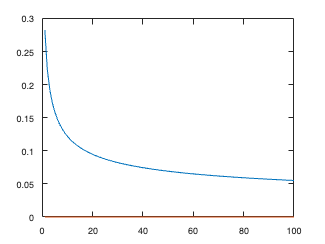

A = rand(100, 400); % generate A
[~, n] = size(A);

% generate ground truth
xsol = ones(n,1) / n;
xsol(180:200,:) = 5;
xsol(300:302,:) = 2;
xsol = xsol ./ sum(xsol);

b = A * xsol; % generate b

%[x, y, z, inform] = PDCO_KL(A, b, mu, lmda, delta, print);

x = EMDA(A ,b, lmda, 100, plt, 0.8);


disp('Sum of entries of x:')

Sum of entries of x:


disp(sum(x)); 

    1.0000



disp('Res:')

Res:


disp(norm(A*x - b));

    0.0552



disp('RMSE:')

RMSE:


disp(norm(x - xsol)/sqrt(n));

    0.0068



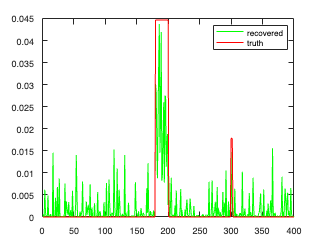


x_ = 1:n;
figure
plot(x_ ,x,'g-', x_, xsol,'r')
legend('recovered', 'truth')

### **PhysicsData**

data = load('data/PhysicsData.mat');
A = data.A;
b = data.b;
b = b'; % reshape
x0 = data.x0;
x0 = x0'; % reshape

[~, n] = size(A);

% code to find the best "learning rate" L by comparing |x-x0|/sqrt(n)

s = svds(A, 1, "largest");
L_f = (1/lmda) * (s^2 + norm(A'*b)); 
fprintf('Actual Lipshitz constant: L_f = %f\n', L_f); 

Actual Lipshitz constant: L_f = 22811.669915



Ls = logspace(-2, 6, 100);

min_rmse = inf;
best_L = NaN;

for i = 1:length(Ls)
    L = Ls(i);
    x = EMDA(A, b, lmda, 100, 0, L);
    rmse = norm(x0 - x)/sqrt(n);
    if rmse < min_rmse
        min_rmse = rmse;
        best_L = L;
    end
end

fprintf('Best: L = (%f) | RMSE: = %f\n', best_L, min_rmse); 

Best: L = (11.768120) | RMSE: = 0.001810


#### RMSE, Residual, and visualization

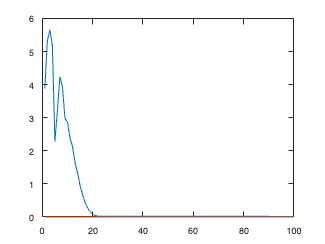

x = EMDA(A, b, lmda, 100, plt, best_L); 


disp('PhysicsData');

PhysicsData


disp('Sum of entries of x:')

Sum of entries of x:


disp(sum(x)); 

     1



disp('Res:')

Res:


disp(norm(A*x - b));

    0.0184



disp('RMSE:')

RMSE:


disp(norm(x - x0)/sqrt(n));

    0.0018



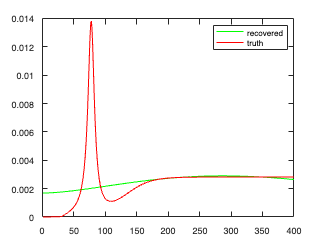


x_ = 1:n;
figure
plot(x_ ,x,'g-', x_, x0,'r')
legend('recovered', 'truth')

### **Synthetic data**

data = load('data/synthetic_data.mat');
A = data.A;
b = data.b;
b = b'; % reshape
x0 = data.x;
x0 = x0'; % reshape

[~, n] = size(A);

As seen in the below code, x0 is not normalized and so we must make a choice to either normalize b by sum(x0) or by b(1) (see Section 8.2 of notes). In this case, lets normalize by sum(x0).

sum(x0)

ans = single
6.3281

b(1)

ans = 6.4728

% Normalization
nrmlzd_b = double(b ./ sum(x0));

% code to find the best "learning rate" L by comparing |x-x0|/sqrt(n)

s = svds(A, 1, "largest");
L_f = (1/lmda) * (s^2 + norm(A'*b)); 
fprintf('Actual Lipshitz constant: L_f = %f\n', L_f); 

Actual Lipshitz constant: L_f = 2591.604885



Ls = logspace(-1, 5, 100);

min_rmse = inf;
best_L = NaN;

for i = 1:length(Ls)
    L = Ls(i);
    x = EMDA(A, b, lmda, 100, 0, L);
    x = sum(x0) * x; % We "undo" the normalization in the solution 
    rmse = norm(x0 - x)/sqrt(n);
    if rmse < min_rmse
        min_rmse = rmse;
        best_L = L;
    end
end

fprintf('Best: L = (%f) | RMSE: = %f\n', best_L, min_rmse); 

Best: L = (9326.033469) | RMSE: = 0.050065


#### RMSE, Residual, and visualization

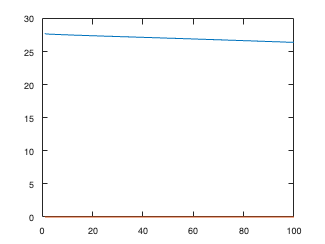

x = EMDA(A, b, lmda, 100, plt, best_L); 


disp('PhysicsData');

PhysicsData


disp('Sum of entries of x:')

Sum of entries of x:


disp(sum(x)); 

    1.0000



disp('Res:')

Res:


disp(norm(A*x - b));

   26.3839



disp('RMSE:')

RMSE:


disp(norm(x - x0)/sqrt(n));

    0.0591



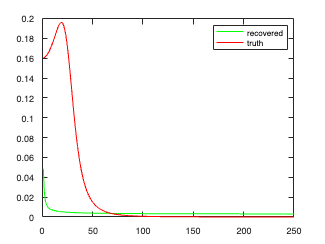


x_ = 1:n;
figure
plot(x_ ,x,'g-', x_, x0,'r')
legend('recovered', 'truth')